# Taking a Selfie Using a Webcam

This example shows how to use the `snapshot` function to acquire live images from USB webcams.

MATLAB® Support Package for USB Webcams provides the ability to bring live images from any USB video class (UVC) compliant webcam into MATLAB. 

## Identifying Available Webcams

The `webcamlist` function provides a cell array of webcams on the current system that MATLAB can access.

camList = webcamlist

camList = 1x1 cell array
    {'Integrated Camera'}


## Set up Connection to Webcam

A webcam object represents the connection between MATLAB® and the USB webcam. To create a connection to the webcam, use the `webcam` function and indicate what camera to connect to. You can specify the camera either by name or index as returned by `webcamlist`. Once the connection is established, you can access specific property values by using the dot(.) notation. 

% Connect to the webcam.
cam = webcam(camList{end})

cam =   webcam with properties:

                    Name: 'Integrated Camera'
              Resolution: '640x480'
    AvailableResolutions: {'640x480'}


## Preview Video Stream

To open a video preview window, use the `preview` function. The video preview window displays the live video stream from the device. 

preview(cam);

## Acquire a Frame

To acquire a single frame, use the `snapshot` function.

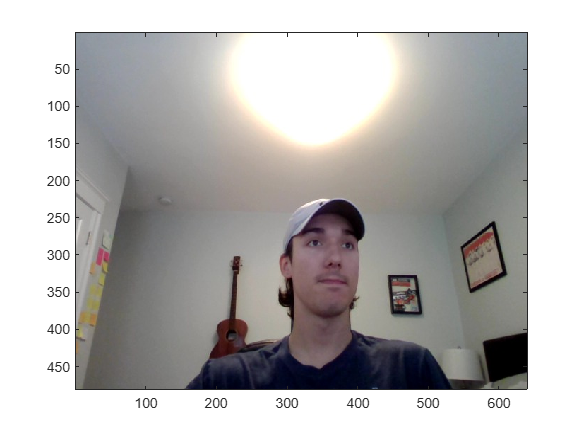

img = snapshot(cam);

% Display the frame in a figure window.
image(img);

closePreview(cam);

## Apply Image Filters and Effects

To alter the appearance of the image, you can use filters and effects. 

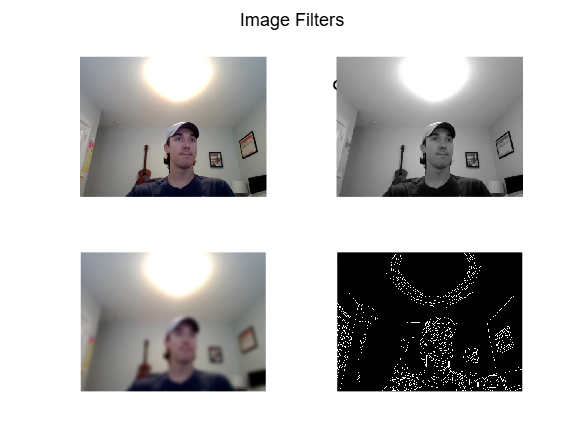

% Display the original image
figure;
subplot(2, 2, 1);
imshow(img);
title('Original Image');

% Convert the image to grayscale
grayImg = rgb2gray(img);
subplot(2, 2, 2);
imshow(grayImg);
title('Grayscale Image');

% Apply Gaussian blur
blurredImg = imgaussfilt(img, 6);
subplot(2, 2, 3);
imshow(blurredImg);
title('Gaussian Blur');

% Apply edge detection using the Canny method
edges = edge(grayImg, 'Canny');
subplot(2, 2, 4);
imshow(edges);
title('Edge Detection');

sgtitle('Image Filters');

## Clean Up

Once the connection is no longer needed, clear the associated variable.

clear cam

© COPYRIGHT 2024 by The MathWorks®, Inc.